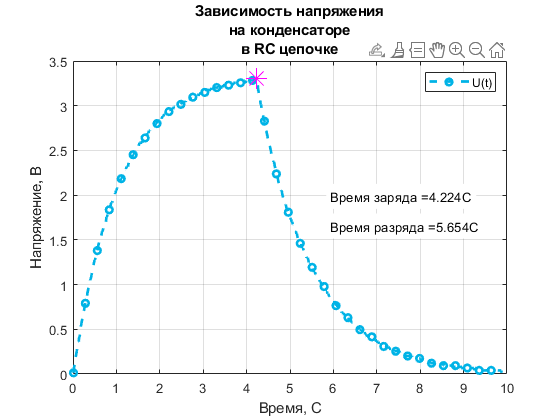

close all;
clear variables;


data = importdata("data.txt");
scale = importdata("settings.txt");
dV = scale(1);
dt = scale (2);
U = data * dV;
t = ((1:length(data)) * dt)';
tmax=max(t);
[capmax,imaxcharge]=max(U);
tCharge=t(imaxcharge);
tDischarge=tmax-tCharge;

f1 = figure();
plot(t,U,'g--o','MarkerIndices',1:25:length(U),'LineWidth',2,'MarkerSize',5,'Color',[0,0.7,0.9]);
hold on;
plot(tCharge,capmax,'m*','Markersize',15);
hold off;
grid on;
title({'Зависимость напряжения', 'на конденсаторе','в RC цепочке'});
xlabel("Время, С");
ylabel("Напряжение, В");
legend("U(t)",'Location','northeast');
text(max(t) * 0.6, max(U) * 0.6, ['Время заряда =', num2str(tCharge), 'С'], 'BackgroundColor', 'w');
text(max(t) * 0.6, max(U) * 0.5, ['Время разрядa =', num2str(tDischarge), 'С'], 'BackgroundColor', 'w');
set(gcf,'Visible','on',"Name","Варданян Ашот Артурович Б03-008");

saveas(f1,'cap.png');
saveas(f1,'cap.svg');